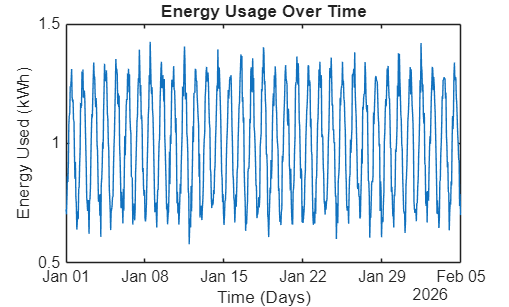

clear
T = readtable("hourly_energy_usage_5_weeks.csv");


energyUsage = T.energy_kWh; 
timeStamps = T.timestamp; 


timeStamps = datetime(timeStamps, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');

plot(timeStamps, energyUsage);
title('Energy Usage Over Time');
xlabel('Time (Days)');
ylabel('Energy Used (kWh)')



desiredStart = datetime(2026,1,1);
desiredEnd   = datetime(2026,2,5);


inRange = timeStamps >= desiredStart & timeStamps <= desiredEnd;
dt = timeStamps(inRange);
eu = energyUsage(inRange);

edges = desiredStart:days(7):desiredEnd+days(1); % +1 day to include final day
bin = discretize(dt, edges);

numBins = numel(edges)-1;
weeklyTotals = zeros(numBins,1);
for k = 1:numBins
    weeklyTotals(k) = sum(eu(bin == k));
end

weekStarts = edges(1:end-1)';

fprintf('Week Start\t\tWeekly Total (kWh)\n');

Week Start		Weekly Total (kWh)


for i = 1:numBins
    fprintf('%s\t%10.2f\n', datestr(weekStarts(i), 'yyyy-mm-dd'), weeklyTotals(i));
end

2026-01-01	    167.67
2026-01-08	    168.63
2026-01-15	    167.96
2026-01-22	    167.45
2026-01-29	    168.17


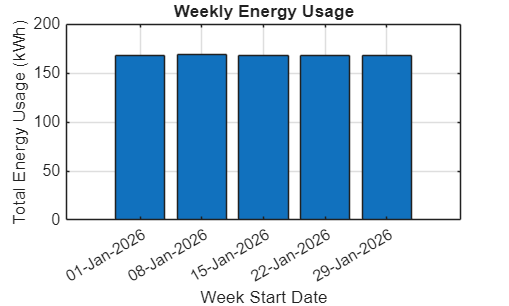


figure;
bar(weekStarts, weeklyTotals);
xlabel('Week Start Date');
ylabel('Total Energy Usage (kWh)');
title('Weekly Energy Usage');
grid on;

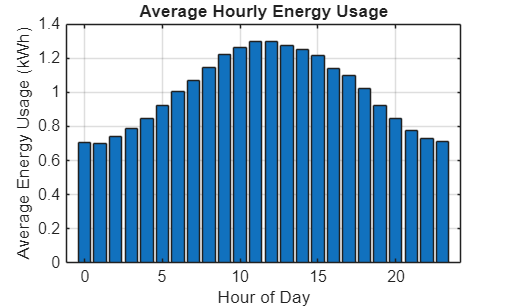


hours = hour(dt);
avgHourlyUsage = zeros(24, 1);
for h = 0:23
    avgHourlyUsage(h + 1) = mean(eu(hours == h));
end
figure;
bar(0:23, avgHourlyUsage);
xlabel('Hour of Day');
ylabel('Average Energy Usage (kWh)');
title('Average Hourly Energy Usage');
grid on;